# EKF

- simple ekf example

- battery ekf implementation

## Simple

% Initialize simulation variables
SigmaW = 1; % Process noise covariance
SigmaV = 2; % Sensor noise covariance
maxIter = 40;

% Seed the random number generator: Octave's "randn" function produces pseudo 
% random numbers having a Gaussian distribution. To get the same random numbers
% every time you run the code, you can "seed" the pseudo random number generator 
% with a deterministic value. This allows us to get reproducible results that 
% still contain apparent randomness.
%
% YOU MUST NOT CHANGE THE FOLLOWING LINE IN ORDER TO ARRIVE AT "CORRECT" ANSWERS 
% FOR THE QUIZ. IF YOU CHANGE IT TO EXPLORE THE BEHAVIOR OF THE FILTER FOR 
% DIFFERENT PSEUDO-RANDOM SEQUENCES, CHANGE IT BACK TO randn("seed",-1) BEFORE 
% COMPUTING RESULTS TO ENTER AS QUIZ RESPONSES.
randn("seed",-1);

% Initialize true state, state estimate, error covariance, initial input
xtrue = 2 + randn(1);  % Initialize true system initial state
xhat = 2;              % Initialize Kalman filter initial estimate
SigmaX = 1;            % Initialize Kalman filter covariance
u = 0;                 % Unknown initial driving input: assume zero

% Reserve storage for variables we might want to plot/evaluate
xstore = zeros(maxIter+1,length(xtrue)); xstore(1,:) = xtrue;
xhatstore = zeros(maxIter,length(xhat));
SigmaXstore = zeros(maxIter,length(xhat)^2);

for k = 1:maxIter,
  % EKF Step 0: Compute Ahat, Bhat
  % Note: For this example, x(k+1) = sqrt(5+x(k)) + w(k)
  Ahat = 0.5/sqrt(5+xhat); Bhat = 1;

  % EKF Step 1: State estimate time update
  % Note: You need to insert your system's f(...) equation here
  xhat = sqrt(5+xhat); 

  % KF Step 2: Error covariance time update
  SigmaX = Ahat*SigmaX*Ahat' + Bhat*SigmaW*Bhat';

  % [Implied operation of system in background, with
  % input signal u, and output signal z]
  w = chol(SigmaW)'*randn(1);
  v = chol(SigmaV)'*randn(1);
  ztrue = xtrue^3 + v;  % z is based on present x and u
  xtrue = sqrt(5+xtrue) + w;  % future x is based on present u

  % KF Step 3: Estimate system output
  % Note: You need to insert your system's h(...) equation here
  Chat = 3*xhat^2; Dhat = 1;
  zhat = xhat^3;

  % KF Step 4: Compute Kalman gain matrix
  L = SigmaX*Chat'/(Chat*SigmaX*Chat' + Dhat*SigmaV*Dhat');

  % KF Step 5: State estimate measurement update
  xhat = xhat + L*(ztrue - zhat);
  xhat = max(-5,xhat); % don't get square root of negative xhat!

  % KF Step 6: Error covariance measurement update
  SigmaX = SigmaX - L*Chat*SigmaX;

  % [Store information for evaluation/plotting purposes]
  xstore(k+1,:) = xtrue;
  xhatstore(k,:) = xhat;
  SigmaXstore(k,:) = SigmaX(:);
end

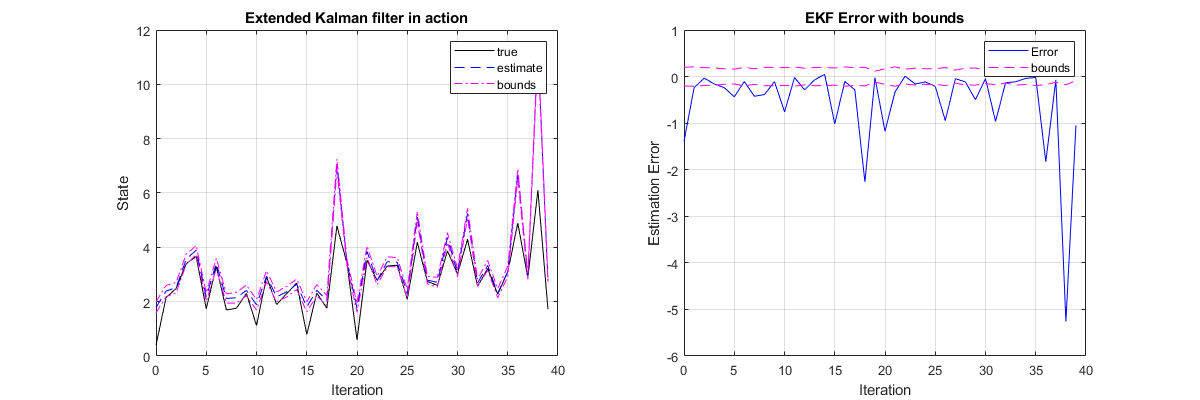

f1 = figure(1); clf;
f1.Position = [0 0 1200 400];
subplot(1,2,1);
plot(0:maxIter-1,xstore(1:maxIter),'k-',0:maxIter-1,xhatstore,'b--', ...
  0:maxIter-1,xhatstore+3*sqrt(SigmaXstore),'m-.',...
  0:maxIter-1,xhatstore-3*sqrt(SigmaXstore),'m-.'); grid;
legend('true','estimate','bounds');
title('Extended Kalman filter in action');
xlabel('Iteration'); ylabel('State');

subplot(1,2,2)
estErr = xstore(1:maxIter)-xhatstore; 
bounds = 3*sqrt(SigmaXstore);
plot(0:maxIter-1,estErr,'b-',0:maxIter-1, bounds,'m--',0:maxIter-1,-bounds,'m--');
grid; legend('Error','bounds');
title('EKF Error with bounds');
xlabel('Iteration'); ylabel('Estimation Error');

% Compute rms error
sqrt(mean(estErr.^2))

ans = 1.0644

% Compute fraction of estimates outside of 3-sigma bounds
length(find(abs(estErr)>bounds))/maxIter

ans = 0.5000

## Battery

% First, make sure that the ESC toolbox functions are in the path
addpath readonly

% Load model file corresponding to a cell of this type
% Has the variables: current, SOC, time, voltage
load readonly/PANdata_P25.mat; % load data from Panasonic NMC cell, +25 degC
T = 25; % Test temperature

time    = DYNData.script1.time(:);   deltat = time(2)-time(1);
time    = time-time(1); % start time at 0
current = DYNData.script1.current(:); % discharge > 0; charge < 0.
voltage = DYNData.script1.voltage(:);
soc     = DYNData.script1.soc(:);

% Load cell-test data to be used for this batch experiment
% Contains variable "DYNData" of which the field "script1" is of 
% interest. This has sub-fields time, current, voltage, soc.
load readonly/PANmodel.mat; % load ESC model of Panasonic NMC cell


% Reserve storage for computed results, for plotting
sochat = zeros(size(soc));
socbound = zeros(size(soc));

% Covariance values
SigmaX0 = diag([1e2 1e-2 1e-3]); % uncertainty of initial state
SigmaV = 3e-1; % Uncertainty of voltage sensor, output equation
SigmaW = 4e0; % Uncertainty of current sensor, state equation

% Create ekfData structure and initialize variables using first
% voltage measurement and first temperature measurement
ekfData = initEKF(voltage(1),T,SigmaX0,SigmaV,SigmaW,model);


% Now, enter loop for remainder of time, where we update the SPKF
% once per sample interval
fprintf('Please be patient. This code will take several minutes to execute.\n');

Please be patient. This code will take several minutes to execute.


for k = 1:length(voltage)
  vk = voltage(k); % "measure" voltage
  ik = current(k); % "measure" current
  Tk = T;          % "measure" temperature
  
  % Update SOC (and other model states)
  [sochat(k),socbound(k),ekfData] = iterEKF(vk,ik,Tk,deltat,ekfData);
  if mod(k,1000)==0,
    fprintf('  Completed %d out of %d iterations...\n',k,length(voltage));
  end  
end

  Completed 1000 out of 35560 iterations...
  Completed 2000 out of 35560 iterations...
  Completed 3000 out of 35560 iterations...
  Completed 4000 out of 35560 iterations...
  Completed 5000 out of 35560 iterations...
  Completed 6000 out of 35560 iterations...
  Completed 7000 out of 35560 iterations...
  Completed 8000 out of 35560 iterations...
  Completed 9000 out of 35560 iterations...
  Completed 10000 out of 35560 iterations...
  Completed 11000 out of 35560 iterations...
  Completed 12000 out of 35560 iterations...
  Completed 13000 out of 35560 iterations...
  Completed 14000 out of 35560 iterations...
  Completed 15000 out of 35560 iterations...
  Completed 16000 out of 35560 iterations...
  Completed 17000 out of 35560 iterations...
  Completed 18000 out of 35560 iterations...
  Completed 19000 out of 35560 iterations...
  Completed 20000 out of 35560 iterations...
  Completed 21000 out of 35560 iterations...
  Completed 22000 out of 35560 iterations...
  Completed 23000 o

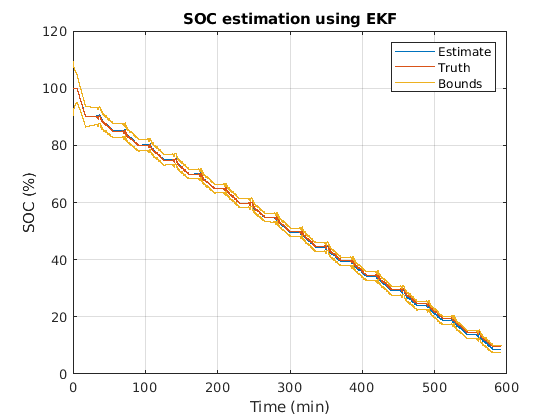

%%
plot(time/60,100*sochat,time/60,100*soc); hold on
plot([time/60; NaN; time/60],[100*(sochat+socbound); NaN; 100*(sochat-socbound)]);
title('SOC estimation using EKF'); grid on
xlabel('Time (min)'); ylabel('SOC (%)'); legend('Estimate','Truth','Bounds');


%%
fprintf('RMS SOC estimation error = %g%%\n',sqrt(mean((100*(soc-sochat)).^2)));

RMS SOC estimation error = 0.423077%


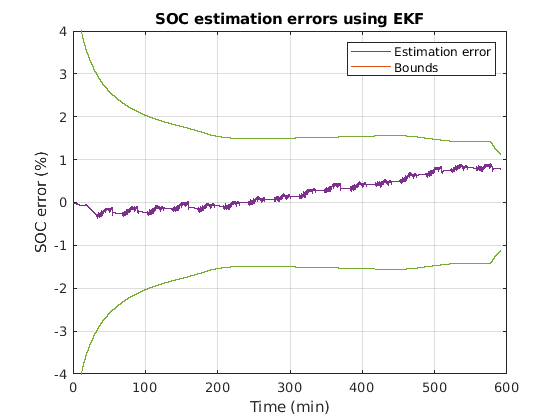

%%
plot(time/60,100*(soc-sochat)); hold on
plot([time/60; NaN; time/60],[100*socbound; NaN; -100*socbound]);
title('SOC estimation errors using EKF');
xlabel('Time (min)'); ylabel('SOC error (%)'); ylim([-4 4]); 
legend('Estimation error','Bounds'); 
grid on


ind = find(abs(soc-sochat)>socbound);
fprintf('Percent of time error outside bounds = %g%%\n',length(ind)/length(soc)*100);

Percent of time error outside bounds = 0%


load readonly/PANmodel.mat


function ekfData = initEKF(v0,T0,SigmaX0,SigmaV,SigmaW,model)

  % Initial state description
  ir0   = 0;                           ekfData.irInd = 1;
  hk0   = 0;                           ekfData.hkInd = 2;
  SOC0  = SOCfromOCVtemp(v0,T0,model); ekfData.zkInd = 3;
  ekfData.xhat  = [ir0 hk0 SOC0]'; % initial state

  % Covariance values
  ekfData.SigmaX = SigmaX0;
  ekfData.SigmaV = SigmaV;
  ekfData.SigmaW = SigmaW;
  ekfData.Qbump = 5;
  
  % previous value of current
  ekfData.priorI = 0;
  ekfData.signIk = 0;
  
  % store model data structure too
  ekfData.model = model;
end


function [zk,zkbnd,ekfData] = iterEKF(vk,ik,Tk,deltat,ekfData)
  model = ekfData.model;
  % Load the cell model parameters
  Q  = getParamESC('QParam',Tk,model);
  G  = getParamESC('GParam',Tk,model);
  M  = getParamESC('MParam',Tk,model);
  M0 = getParamESC('M0Param',Tk,model);
  RC = exp(-deltat./abs(getParamESC('RCParam',Tk,model)))';
  R  = getParamESC('RParam',Tk,model)';
  R0 = getParamESC('R0Param',Tk,model);
  eta = getParamESC('etaParam',Tk,model);
  if ik<0, ik=ik*eta; end;
  
  % Get data stored in ekfData structure
  I = ekfData.priorI;
  SigmaX = ekfData.SigmaX;
  SigmaV = ekfData.SigmaV;
  SigmaW = ekfData.SigmaW;
  xhat = ekfData.xhat;
  irInd = ekfData.irInd;
  hkInd = ekfData.hkInd;
  zkInd = ekfData.zkInd;
  if abs(ik)>Q/100, ekfData.signIk = sign(ik); end;
  signIk = ekfData.signIk;
  
  % EKF Step 0: Compute Ahat[k-1], Bhat[k-1]
  nx = length(xhat); 
  Ahat = zeros(nx,nx); 
  Bhat = zeros(nx,1);
  Ahat(zkInd,zkInd) = 1; 
  Bhat(zkInd) = -deltat/(3600*Q);
  Ahat(irInd,irInd) = diag(RC); 
  Bhat(irInd) = 1-RC(:);
  Ah  = exp(-abs(I*G*deltat/(3600*Q)));  % hysteresis factor
  Ahat(hkInd,hkInd) = Ah;
  B = [Bhat, 0*Bhat];
  Bhat(hkInd) = -abs(G*deltat/(3600*Q))*Ah*(1+sign(I)*xhat(hkInd));
  B(hkInd,2) = Ah-1;
  
  % Step 1a: State estimate time update
  xhat = Ahat*xhat + B*[I; sign(I)]; 
  
  % Step 1b: Error covariance time update
  %          sigmaminus(k) = Ahat(k-1)*sigmaplus(k-1)*Ahat(k-1)' + ...
  %                          Bhat(k-1)*sigmawtilde*Bhat(k-1)'
  SigmaX = Ahat*SigmaX*Ahat' + Bhat*SigmaW*Bhat';
  
  % Step 1c: Output estimate
  yhat = OCVfromSOCtemp(xhat(zkInd),Tk,model) + M0*signIk + ...
         M*xhat(hkInd) - R*xhat(irInd) - R0*ik;
  
  % Step 2a: Estimator gain matrix
  Chat = zeros(1,nx);
  Chat(zkInd) = dOCVfromSOCtemp(xhat(zkInd),Tk,model);
  Chat(hkInd) = M;
  Chat(irInd) = -R;
  Dhat = 1;
  SigmaY = Chat*SigmaX*Chat' + Dhat*SigmaV*Dhat';
  L = SigmaX*Chat'/SigmaY;
  
  % Step 2b: State estimate measurement update
  r = vk - yhat; % residual.  Use to check for sensor errors...
  if r^2 > 100*SigmaY, L(:)=0.0; end % ignore measurement if erronous
  
  xhat = xhat + L*r;
  xhat(hkInd) = min(1,max(-1,xhat(hkInd))); % Help maintain robustness
  xhat(zkInd) = min(1.05,max(-0.05,xhat(zkInd)));
  
  % Step 2c: Error covariance measurement update
  SigmaX = SigmaX - L*SigmaY*L';
  %   % Q-bump code
  if r^2 > 4*SigmaY, % bad voltage estimate by 2 std. devs, bump Q 
    fprintf('Bumping SigmaX\n');
    SigmaX(zkInd,zkInd) = SigmaX(zkInd,zkInd)*ekfData.Qbump;
  end
  [~,S,V] = svd(SigmaX);
  HH = V*S*V';
  SigmaX = (SigmaX + SigmaX' + HH + HH')/4; % Help maintain robustness
  
  % Save data in ekfData structure for next time...
  ekfData.priorI = ik;
  ekfData.SigmaX = SigmaX;
  ekfData.xhat = xhat;
  zk = xhat(zkInd);
  zkbnd = 3*sqrt(SigmaX(zkInd,zkInd));
end







